`A neuron in the brain can "fire" action potentials - sharp spikes that can be recorded by an electrode when it is close to that neuron. An electrode may be close enough to multiple neurons to be able to capture the spikes from each of these neurons. A spike may have a shape over a very short period of time, e.g. 1ms. Spikes generated by the same neuron may look very similar to each other. Spikes generated by different neurons may be relatively more different from one another. In this project, you are given electrical recordings from 5 electrodes inserted into the brainstem of a rat brain. Each of these electrodes may pick up some spikes. You need to explore the data and find the neuronal spikes from the data. Then you need to identify how many neurons these spikes are generated from. Then for each identified neuron, you need to identify when it fires, and how many times it fires every 10 milliseconds (or firing rate). Lastly, you need to investigate whether the firing rate depends on electrical stimulation of a peripheral nerve on an visceral organ, while the stimulation varies its amplitude. `

`You will see three variables: data is 5-by-T (5 is the number of electrodes or channels) and includes the electrical signals recorded from 5 electrodes. fs is the sampling frequency in Hz, stim is 1-by-T and includes the stimulation with a unit of mA. `

clear
close all
load("data.mat")

`1. How long is the recording in seconds? `

data_length = length(data);
time_length = data_length/fs;
time_span = 0:1/fs:time_length-(1/fs);

disp(['Data is ', num2str(time_length), ' seconds long'])

Data is 926.7057 seconds long


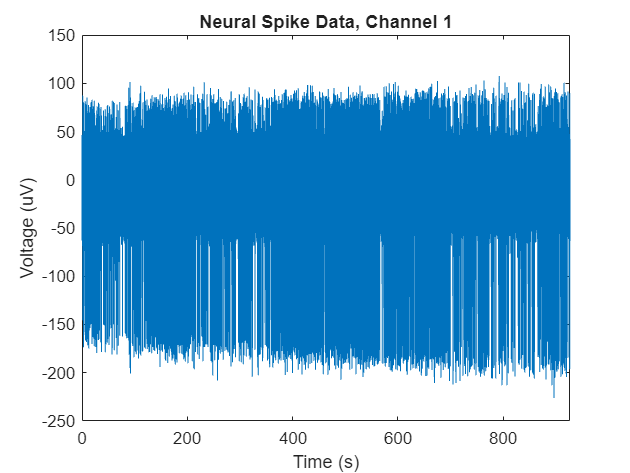

figure()
plot(time_span, data(1,:))
xlim([0 time_span(end)])
xlabel('Time (s)')
ylabel('Voltage (uV)')
title('Neural Spike Data, Channel 1')

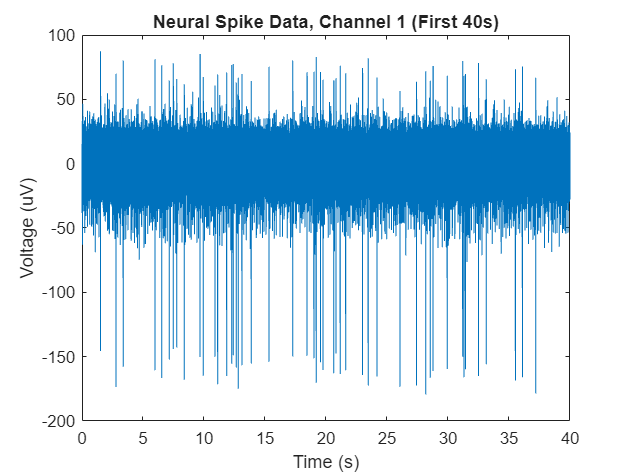

figure()
plot(time_span, data(1,:))
xlim([0 40])
xlabel('Time (s)')
ylabel('Voltage (uV)')
title('Neural Spike Data, Channel 1 (First 40s)')

`2. For each channel, evaluate its mean and standard deviation? `

means = mean(data, 2);
stdevs = std(data, 0, 2);

for i=1:5
    disp(['Channel ', num2str(i), ': Mean=', num2str(means(i)), ', STD=', num2str(stdevs(i))])
end

Channel 1: Mean=-9.2275e-06, STD=10.2116
Channel 2: Mean=-7.7396e-06, STD=9.8801
Channel 3: Mean=-1.0969e-05, STD=15.5161
Channel 4: Mean=-4.0592e-07, STD=10.5794
Channel 5: Mean=-1.0264e-05, STD=9.4291


`3. Evaluate the correlation between every pair of different channels. `

pairs = [1, 2;...
        1, 3;...
        1, 4;...
        1, 5;...
        2, 3;...
        2, 4;...
        2, 5;...
        3, 4;...
        3, 5;...
        4, 5];

coefs = zeros([1, 10]);
for i=1:10
    coef_matrix = corrcoef(data(pairs(i,1), :), data(pairs(i,2), :));
    coefs(i) = coef_matrix(2,1);
    disp(['Correlation between Channel ', num2str(pairs(i, 1)), ' and ', num2str(pairs(i, 2)), ': ', num2str(coefs(i))])
end

Correlation between Channel 1 and 2: 0.49619
Correlation between Channel 1 and 3: 0.10768
Correlation between Channel 1 and 4: 0.14241
Correlation between Channel 1 and 5: 0.15929
Correlation between Channel 2 and 3: 0.11458
Correlation between Channel 2 and 4: 0.15333
Correlation between Channel 2 and 5: 0.1702
Correlation between Channel 3 and 4: 0.10896
Correlation between Channel 3 and 5: 0.11871
Correlation between Channel 4 and 5: 0.45788


`4. For each channel, detect the neuronal spikes. Hint: this is an open-ended question. You need to observe the data first and come up with your own criteria for a spike. Typically, a spike will show a peak that deviates from the baseline (often just the mean) by a notable extent (e.g., multiple times of a standard deviation). The peak may be either positive or negative. Exercise your own judgment. `

window = 0.0005;

peaks_1 = find_spike_peaks(data(1, :), 60, 125, fs, window);
peaks_2 = find_spike_peaks(data(2, :), 75, 75, fs, window);
peaks_3 = find_spike_peaks(data(3, :), 60, 60, fs, window);
peaks_4 = find_spike_peaks(data(4, :), 75, 75, fs, window);
peaks_5 = find_spike_peaks(data(5, :), 50, 75, fs, window);

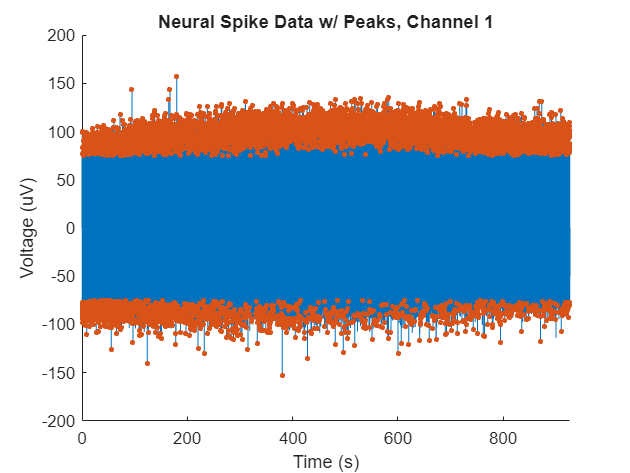

figure()
hold on
plot(time_span, data(4,:))
scatter(time_span(peaks_4), data(4, peaks_4), 10, 'filled')
xlim([0 time_span(end)])
xlabel('Time (s)')
ylabel('Voltage (uV)')
title('Neural Spike Data w/ Peaks, Channel 1')

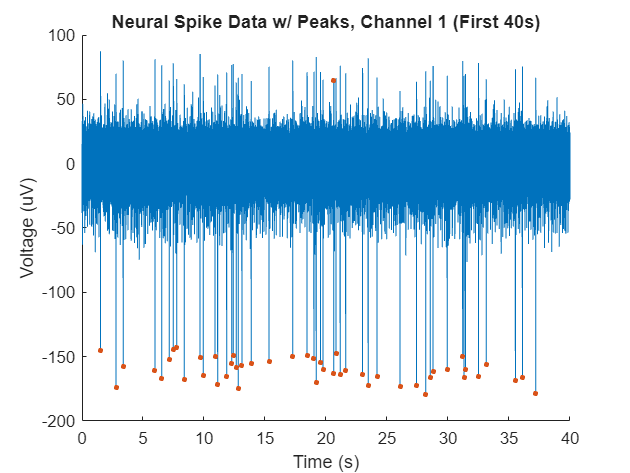

figure()
hold on
plot(time_span(time_span<=100), data(1,time_span<=100))
scatter(peaks_1/fs, data(1, peaks_1), 10, 'filled')
xlim([0 40])
xlabel('Time (s)')
ylabel('Voltage (uV)')
title('Neural Spike Data w/ Peaks, Channel 1 (First 40s)')

`5. For each spike you have detected in 4, choose a short window around the peak of the spike. The window is often very short. You may explore the data and exercise your own judgment. For example, a window may start from 0.5 ms before the peak and 0.5 ms after the peak. The signal within such a window defines the shape of each spike you have detected. `

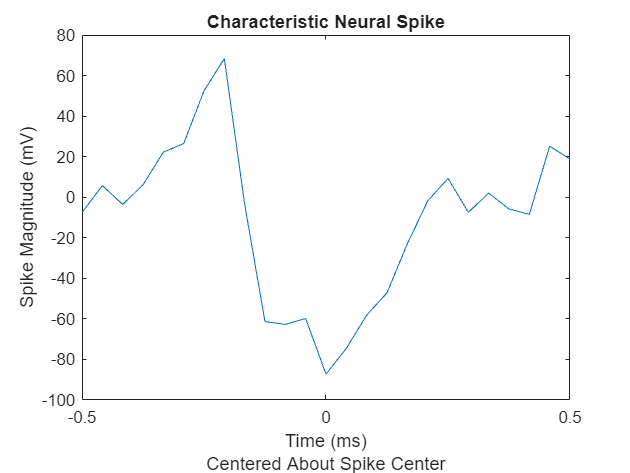

test_spike = spike_shape(data(4,:), peaks_4(104), fs, window);

figure()
test_time = linspace(-1000*window, 1000*window, length(test_spike));
plot(test_time, test_spike)
xlabel({'Time (ms)','Centered About Spike Center'})
ylabel('Spike Magnitude (mV)')
title('Characteristic Neural Spike')

spikes_1 = find_spikes(data(1,:), peaks_1, fs, window);
spikes_2 = find_spikes(data(2,:), peaks_2, fs, window);
spikes_3 = find_spikes(data(3,:), peaks_3, fs, window);
spikes_4 = find_spikes(data(4,:), peaks_4, fs, window);
spikes_5 = find_spikes(data(5,:), peaks_5, fs, window);

`6. Find a way to cluster the spike shape using k-means clustering. Each cluster corresponds to one neuron. Hint: you may define features of each spike using PCA or SVD, or other ways you would come up with. This is again open-ended.`

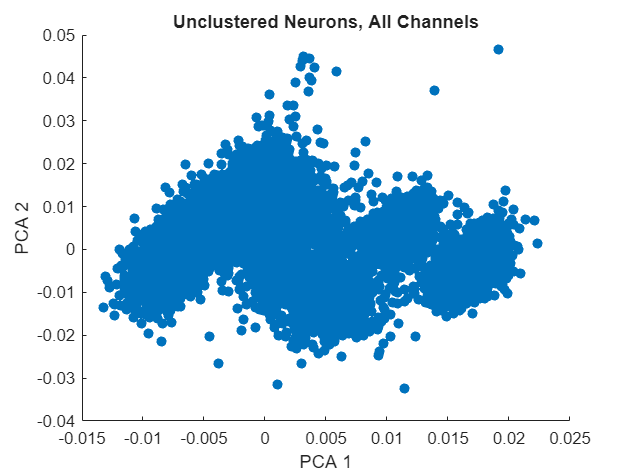

spikes_all = [spikes_1; spikes_2; spikes_3; spikes_4; spikes_5];
spikes_all_coeff= pca(zscore(spikes_all)');

figure()
hold on
scatter(spikes_all_coeff(:, 1), spikes_all_coeff(:, 2), 'filled')
xlabel('PCA 1')
ylabel('PCA 2')
title('Unclustered Neurons, All Channels')

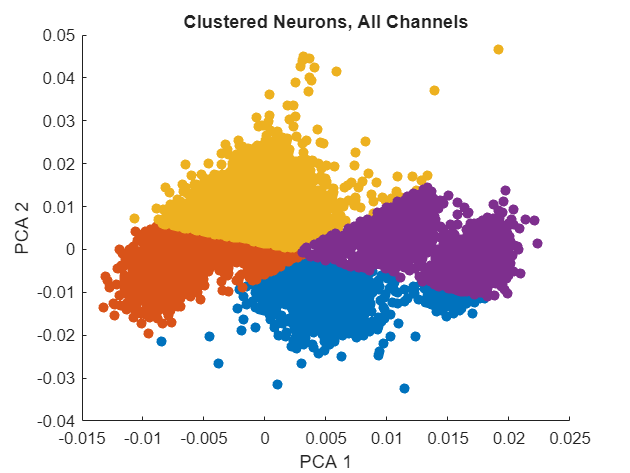

num_clusters = 4;
[idx_all, ~] = kmeans(spikes_all_coeff(:, 1:2), num_clusters);

figure()
hold on
for i=1:num_clusters
    scatter(spikes_all_coeff(idx_all==i,1), spikes_all_coeff(idx_all==i,2), 'filled')
end

xlabel('PCA 1')
ylabel('PCA 2')
title('Clustered Neurons, All Channels')

`7. Justify the number of clusters (or neurons). Calculate the centroid of each cluster. Use this centroid to obtain the average spike shape of each neuron. `

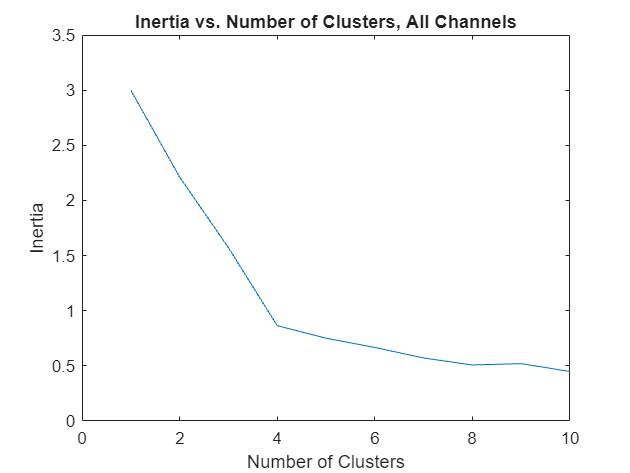

k_max = 10;
inertias = zeros([1 k_max]);

for i=1:k_max
    [~, ~, sumD] = kmeans(spikes_all_coeff(:, 1:3), i);
    inertias(i) = sum(sumD);
end

figure()
plot(1:k_max, inertias)
xlabel('Number of Clusters')
ylabel('Inertia')
title('Inertia vs. Number of Clusters, All Channels')

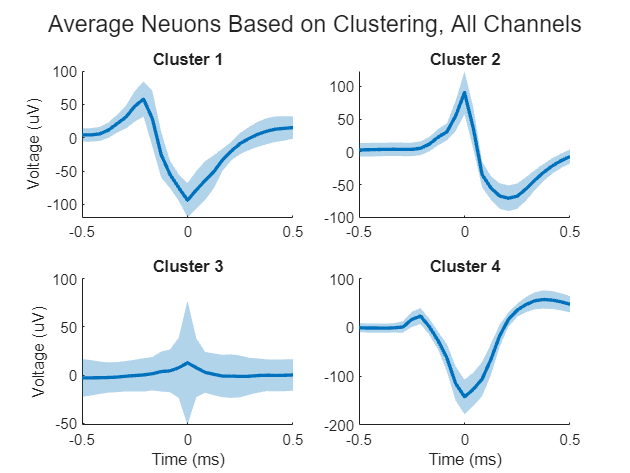

avg_neurons = zeros([num_clusters, round(2*fs*window) + 1]);
std_neurons = zeros([num_clusters, round(2*fs*window) + 1]);

figure()
for i=1:num_clusters
    avg_neurons(i,:) = mean(spikes_all(idx_all==i, :), 1);
    std_neurons(i,:) = std(spikes_all(idx_all==i, :), 1);

    subplot(2,2,i)
    plotEB(test_time, avg_neurons(i,:), std_neurons(i,:))
    if (i==3)||(i==4)
        xlabel('Time (ms)')
    end

    if (i==1)||(i==3)
        ylabel('Voltage (uV)')
    end
    title(['Cluster ', num2str(i)])
end
sgtitle('Average Neuons Based on Clustering, All Channels')

`8. Repeat the analysis for each channel separately. `

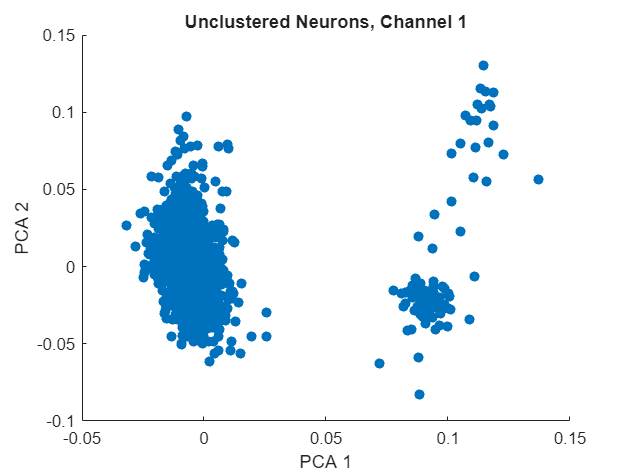

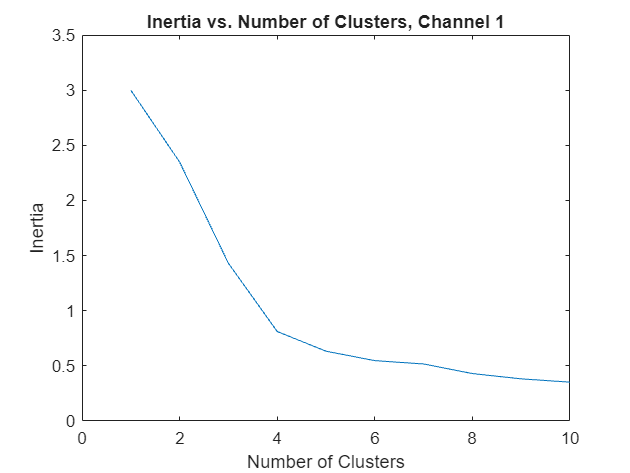

spikes_1_coeff = cluster_spikes(spikes_1, k_max, 1);

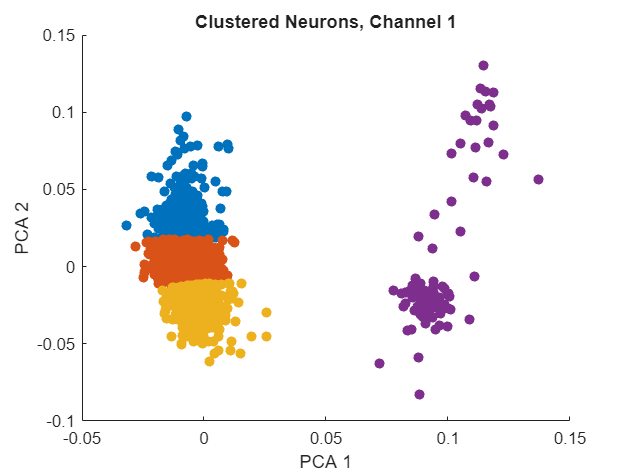


[idx_1, ~] = kmeans(spikes_1_coeff(:, 1:2), 4);

figure()
hold on
for i=1:k_max
    scatter(spikes_1_coeff(idx_1==i,1), spikes_1_coeff(idx_1==i,2), 'filled')
end
xlabel('PCA 1')
ylabel('PCA 2')
title('Clustered Neurons, Channel 1')

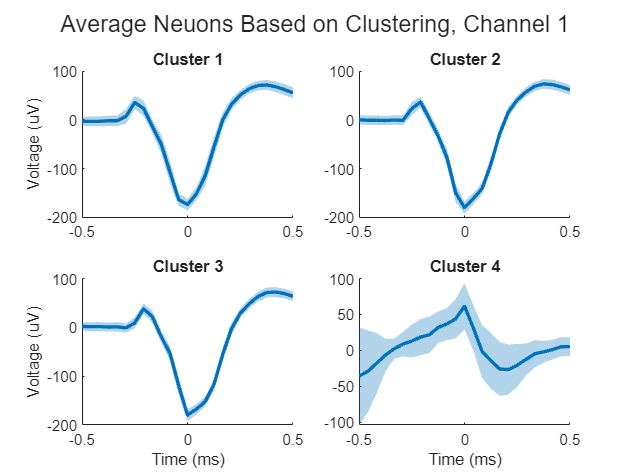

avg_spikes(test_time, spikes_1, idx_1, 4, 2, 2, 1)

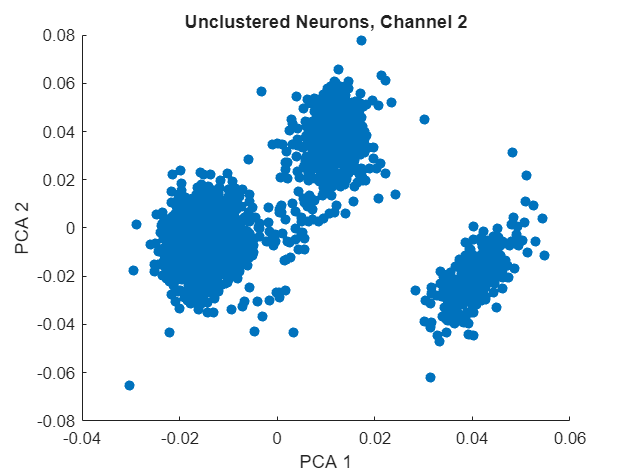

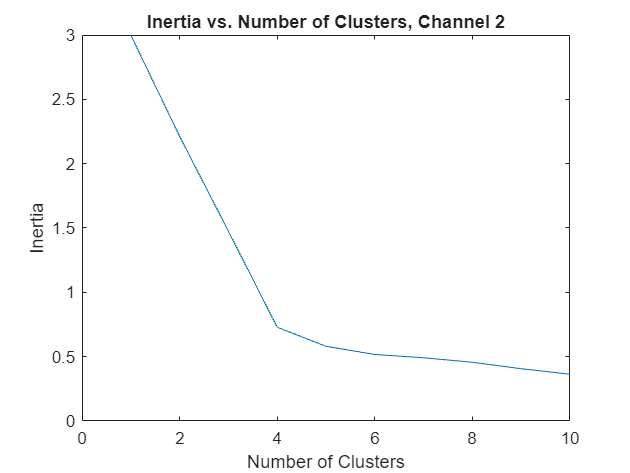

spikes_2_coeff = cluster_spikes(spikes_2, k_max, 2);

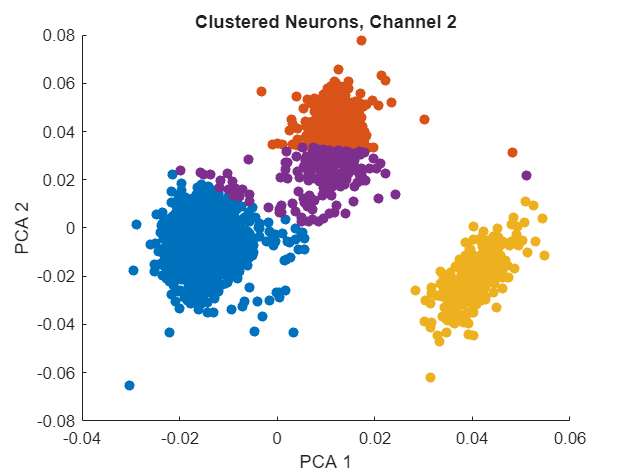


[idx_2, ~] = kmeans(spikes_2_coeff(:, 1:2), 4);

figure()
hold on
for i=1:k_max
    scatter(spikes_2_coeff(idx_2==i,1), spikes_2_coeff(idx_2==i,2), 'filled')
end
xlabel('PCA 1')
ylabel('PCA 2')
title('Clustered Neurons, Channel 2')

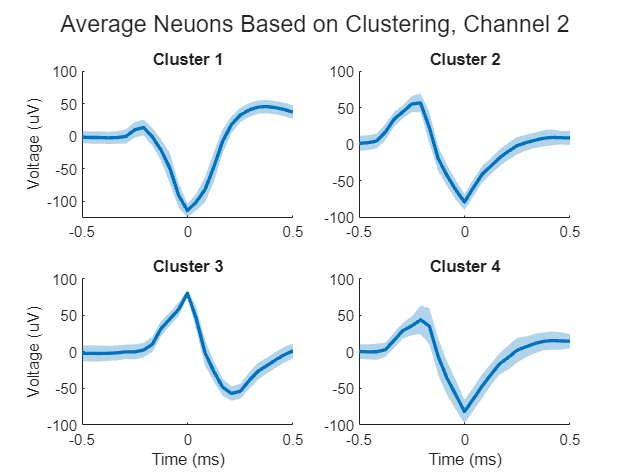

avg_spikes(test_time, spikes_2, idx_2, 4, 2, 2, 2)

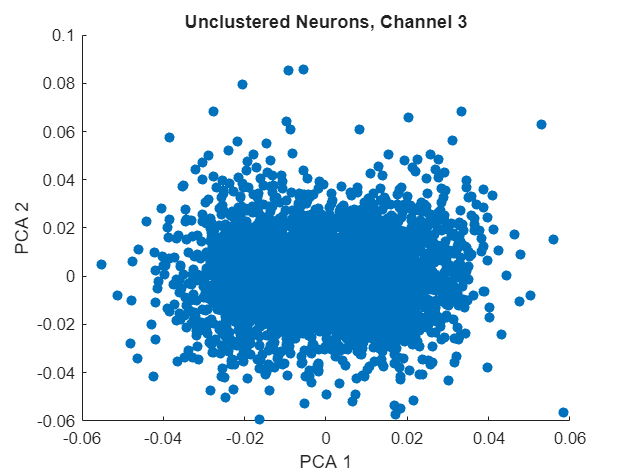

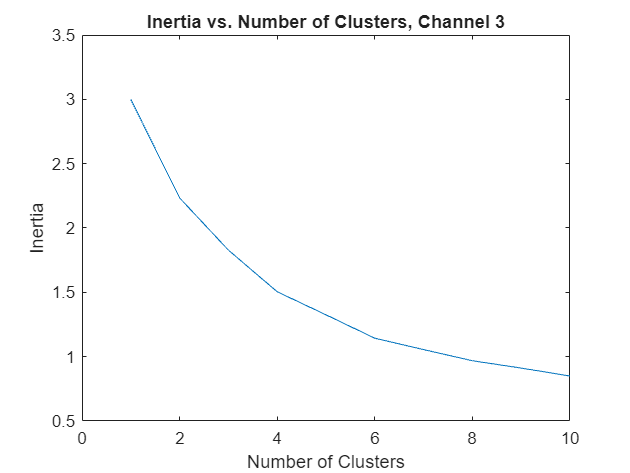

spikes_3_coeff = cluster_spikes(spikes_3, k_max, 3);

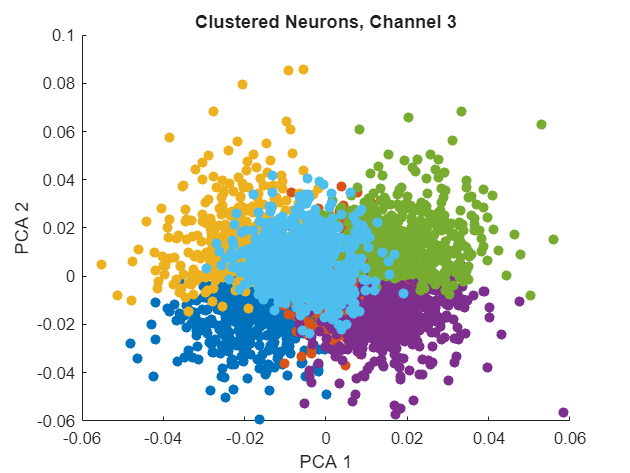


[idx_3, ~] = kmeans(spikes_3, 6);

figure()
hold on
for i=1:k_max
    scatter(spikes_3_coeff(idx_3==i,1), spikes_3_coeff(idx_3==i,2), 'filled')
end
xlabel('PCA 1')
ylabel('PCA 2')
title('Clustered Neurons, Channel 3')

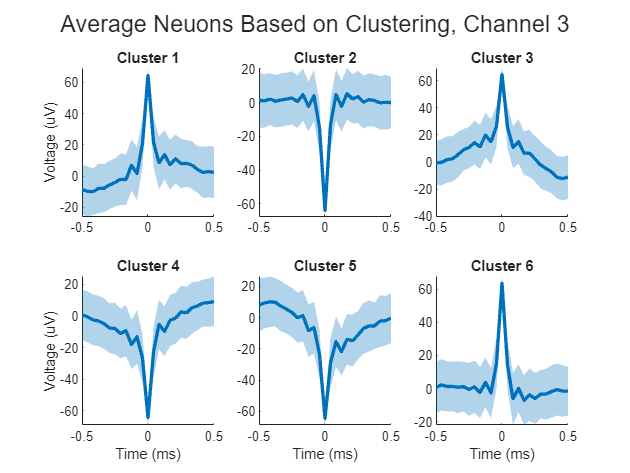

avg_spikes(test_time, spikes_3, idx_3, 6, 2, 3, 3)

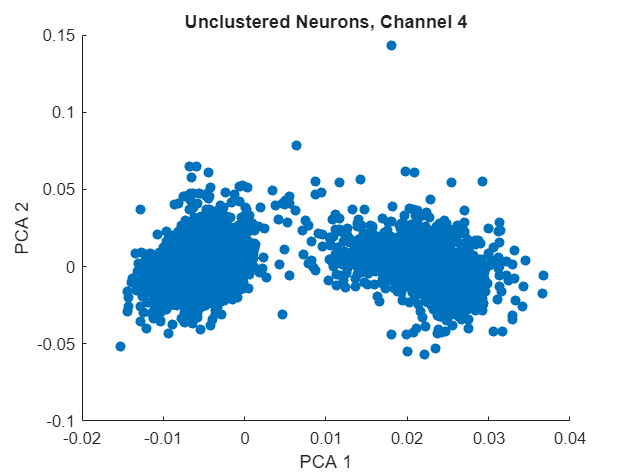

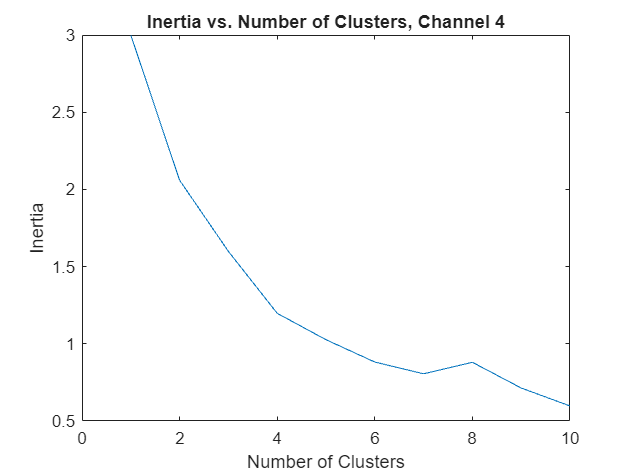

spikes_4_coeff = cluster_spikes(spikes_4, k_max, 4);

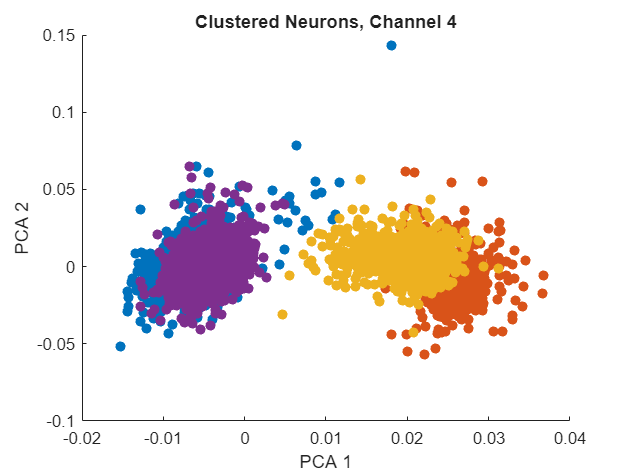


[idx_4, ~] = kmeans(spikes_4, 4);

figure()
hold on
for i=1:k_max
    scatter(spikes_4_coeff(idx_4==i,1), spikes_4_coeff(idx_4==i,2), 'filled')
end
xlabel('PCA 1')
ylabel('PCA 2')
title('Clustered Neurons, Channel 4')

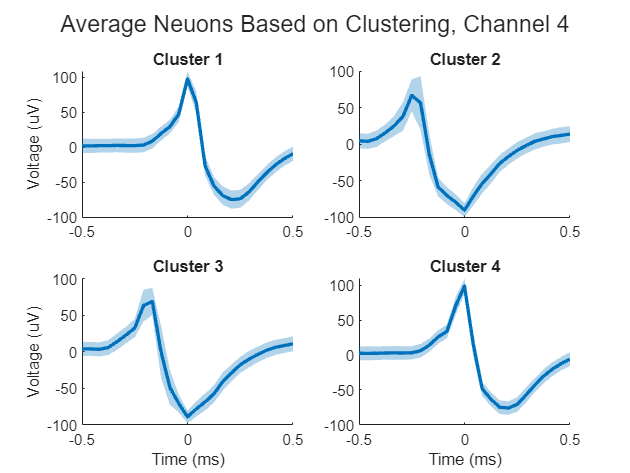

avg_spikes(test_time, spikes_4, idx_4, 4, 2, 2, 4)

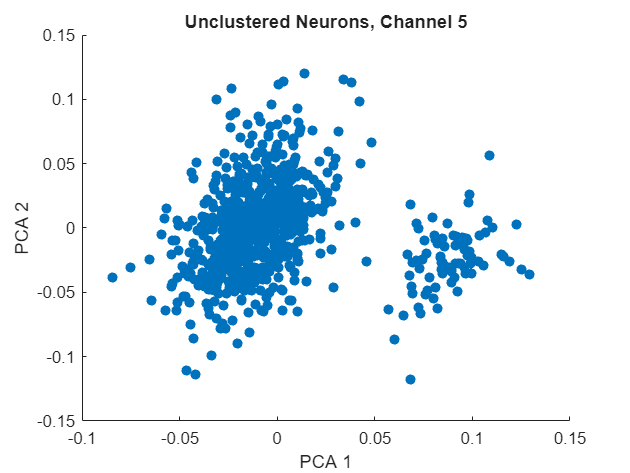

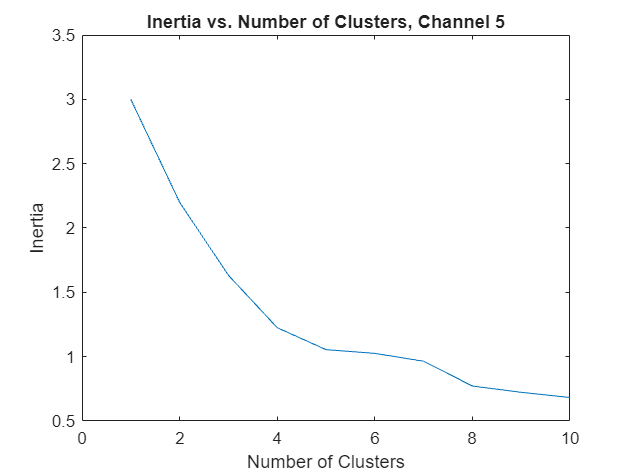

spikes_5_coeff = cluster_spikes(spikes_5, k_max, 5);

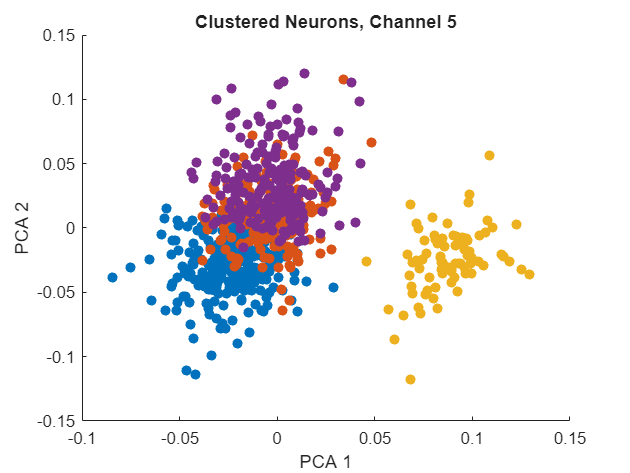


[idx_5, ~] = kmeans(spikes_5, 4);

figure()
hold on
for i=1:k_max
    scatter(spikes_5_coeff(idx_5==i,1), spikes_5_coeff(idx_5==i,2), 'filled')
end
xlabel('PCA 1')
ylabel('PCA 2')
title('Clustered Neurons, Channel 5')

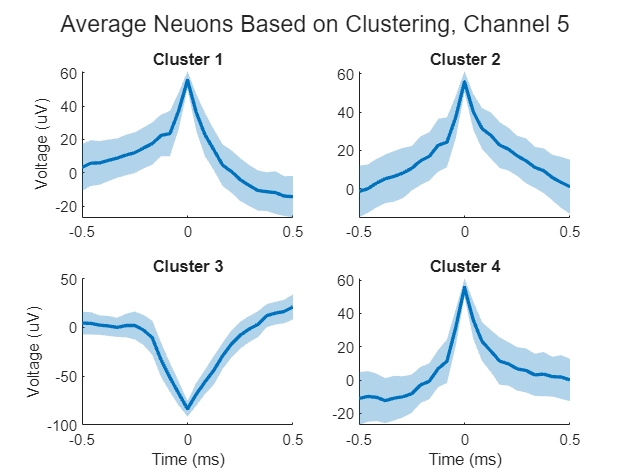

avg_spikes(test_time, spikes_5, idx_5, 4, 2, 2, 5)

`9. Calculate the firing rate of each neuron detected. That is to count how many times each neuron fire within a 10-s moving window. `

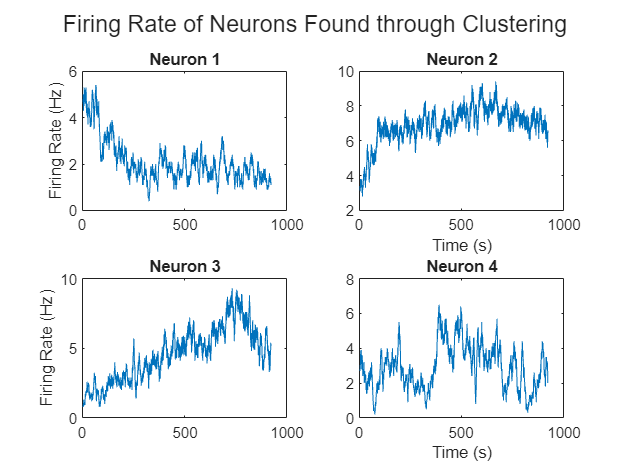

peaks_all = [peaks_1'; peaks_2'; peaks_3'; peaks_4'; peaks_5';];
neuron_1_peaks = peaks_all(idx_all==1);
neuron_2_peaks = peaks_all(idx_all==2);
neuron_3_peaks = peaks_all(idx_all==3);
neuron_4_peaks = peaks_all(idx_all==4);

mid_times = round(5*fs):round(fs*.01):round(data_length-5*fs);
fr_time = linspace(5, time_length-5, length(mid_times));
firing_rates = zeros([4 length(mid_times)]);
for i=1:length(mid_times)
    firing_rates(1, i) = length(neuron_1_peaks((mid_times(i)-round(5*fs) < neuron_1_peaks)&(neuron_1_peaks < mid_times(i)+round(5*fs))))/10;
    firing_rates(2, i) = length(neuron_2_peaks((mid_times(i)-round(5*fs) < neuron_2_peaks)&(neuron_2_peaks < mid_times(i)+round(5*fs))))/10;
    firing_rates(3, i) = length(neuron_3_peaks((mid_times(i)-round(5*fs) < neuron_3_peaks)&(neuron_3_peaks < mid_times(i)+round(5*fs))))/10;
    firing_rates(4, i) = length(neuron_4_peaks((mid_times(i)-round(5*fs) < neuron_4_peaks)&(neuron_4_peaks < mid_times(i)+round(5*fs))))/10;
end

`10. Evaluate the temporal fluctuation of each neuron's firing rate. `

figure()
for i=1:4
    subplot(2,2,i)
    plot(fr_time, firing_rates(i,:))
    if (i==2)||(i==4)
        xlabel('Time (s)')
    end

    if (i==1)||(i==3)
        ylabel('Firing Rate (Hz)')
    end

    title(['Neuron ', num2str(i)])
end
sgtitle('Firing Rate of Neurons Found through Clustering')

`11. Explore the relationship between the firing rate and the stimulation delivered to the peripheral nerve. `

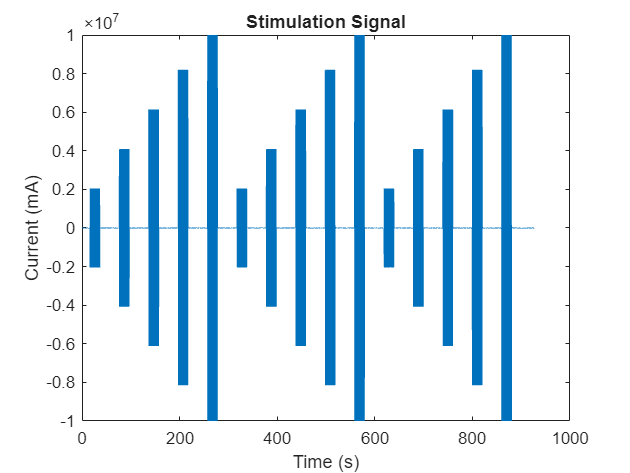

figure()
plot(time_span, stim)
xlabel('Time (s)')
ylabel('Current (mA)')
title('Stimulation Signal')

coefs_stim = zeros([1 4]);
for i=1:4
    coef_matrix = corrcoef(firing_rates(i,:), stim(mid_times));
    coefs_stim(i) = coef_matrix(2,1);
    disp(['Correlation between Neuron ', num2str(i), ' and Stim Signal: ', num2str(coefs_stim(i))])
end

Correlation between Neuron 1 and Stim Signal: -0.00015922
Correlation between Neuron 2 and Stim Signal: 0.00070657
Correlation between Neuron 3 and Stim Signal: 0.0013081
Correlation between Neuron 4 and Stim Signal: 0.0003782
